# Two-photon microscopy data analysis

This notebook is designed to analyze data obtained from two-photon microscopy, specifically for the Cold Spring Harbor Laboratory (CSHL) Drosophila Neurobiology course.

The analysis will focus on various aspects of the collected data, including visualizing the volumes, registering the volumes, image processing, quantification of neuronal activity, and visualization of results.

The goal is to provide a short introduction to analyzing datasets obtained from two-photon microscopy. 

## Setup libraries and folder locations

Here I load the required libraries, setup the data folders, etc. 

% Set folder names
curr_folder = pwd;

dataset_name = '20240706a_00004_00001.tif'

repo_folder = fullfile(curr_folder, '..');
data_folder = fullfile(repo_folder, 'data');

% Dataset name
dataset_name = '20240706a_00004_00001.tif'

% Load external libraries (that in in toolbox)
addpath(genpath(fullfile(pwd, 'toolbox/')));

## Loading and visualizing datasets

In this section, we will load the dataset and visualize the volume as well as the linked metadata acquired during imaging. We will be using the scanimage library to load the tiff.

The below guide assumes that the two-photon microscope you are using saves the data as TIFF files (generally true as this is the default format).

### Load dataset

% Import Tiff Reader
import ScanImageTiffReader.ScanImageTiffReader;

Size of volumes: 128    128  17000



% Setup reader to load dataset
reader = ScanImageTiffReader(fullfile(data_folder, dataset_name));

Number of images in volumes: 17000


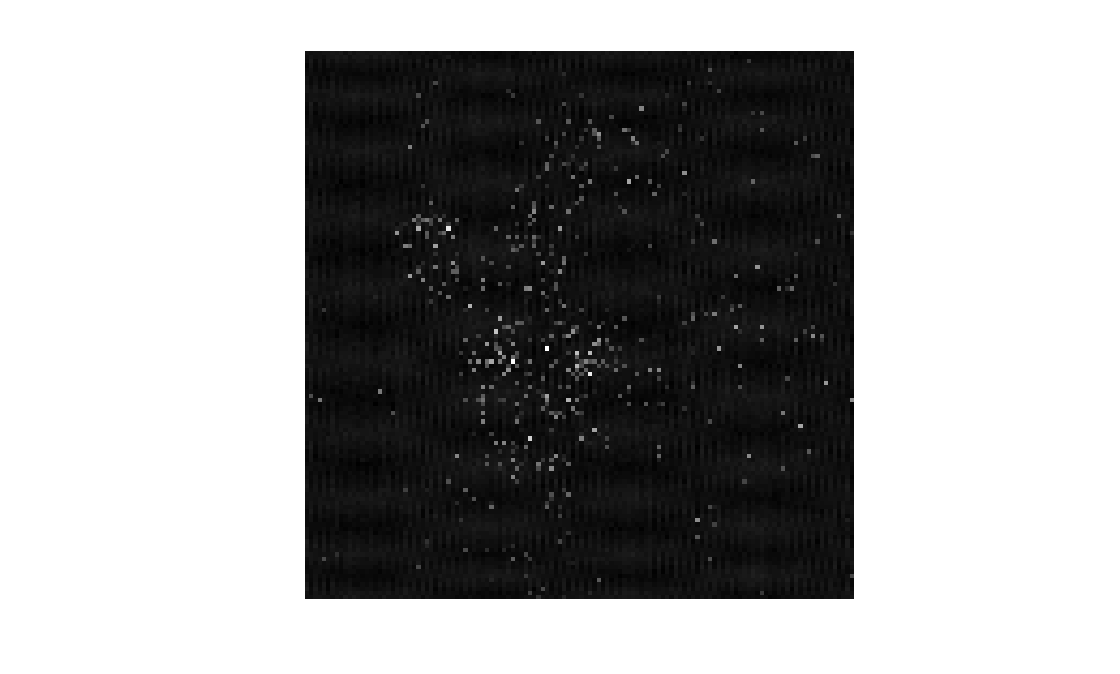


% Load dataset

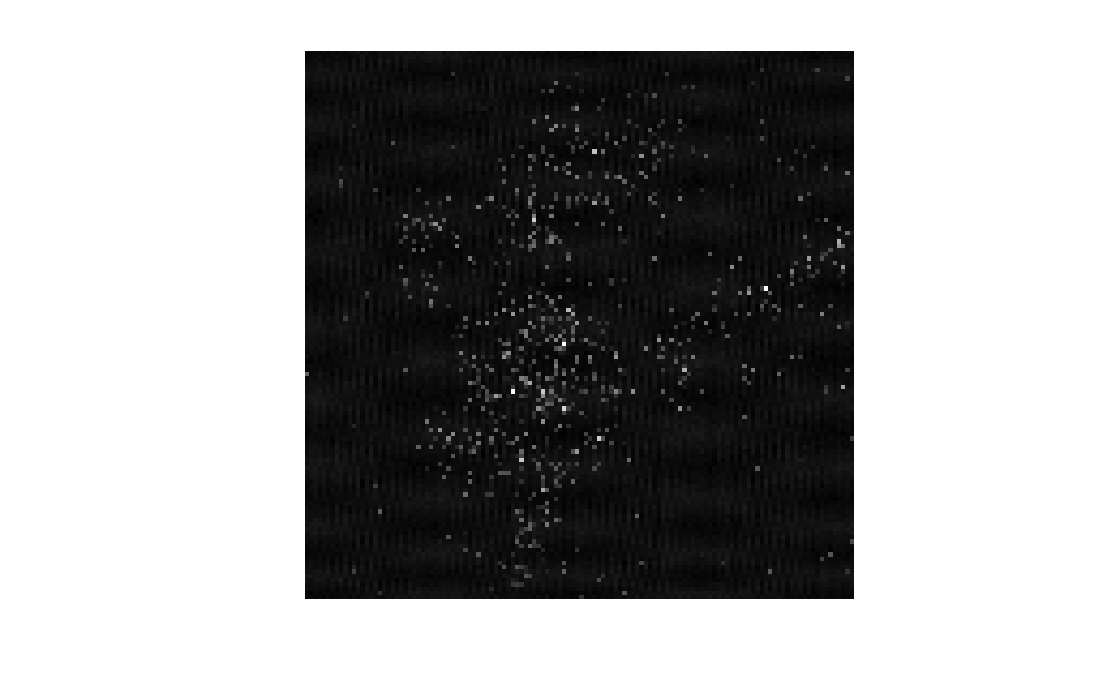

volumes = reader.data(); % Load the volumes from the TIFF dataset
metadata = reader.metadata(); % Load metadata


### Visualizing images dataset

Volumes are stored as 3D arrays, i.e. a stack of images (like the ImageJ / Fiji visualization). The first two dimensions are the image resolution, the third dimension is number of such images that are acquired. They are technically not volumes as there is no information about the depth of acqusition for each image.

We can do some exploratory investigation by looking at the dimensions, the number of images in the stack and visualize individual images.

% Learn more about the volumes
disp(['Size of volumes: ', num2str(size(volumes))]);

metadata_lines = 472×1 cell array
    {'SI.LINE_FORMAT_VERSION = 1'                                    }
    {'SI.PREMIUM = true'                                             }
    {'SI.TIFF_FORMAT_VERSION = 4'                                    }
    {'SI.VERSION_COMMIT = '2af5d7cfec2f1f15c7a4f5cfcb6b56de9e5d4a1d''}
    {'SI.VERSION_MAJOR = 2021'                                       }
    {'SI.VERSION_MINOR = 1'                                          }
    {'SI.VERSION_UPDATE = 0'                                         }
    {'SI.acqState = 'grab''                                          }
    {'SI.acqsPerLoop = 1'                                            }
    {'SI.errorMsg = '''                                              }
    {'SI.extTrigEnable = false'                                      }
    {'SI.fieldCurvatureRxs = []'                                     }
    {'SI.fieldCurvatureRys = []'                                     }
    {'SI.fieldCurvatureTilt = 0'           

image_count = size(volumes, 3);
image_selection = image_count/500; % variable for the slider step
disp(['Number of images in volumes: ', num2str(image_count)])
% Show the first image in the stack with automatic grayscale scaling and magnify it (128x128 is too small)

f_meta = struct with fields:
       LINE_FORMAT_VERSION: 1
                   PREMIUM: 1
       TIFF_FORMAT_VERSION: 4
            VERSION_COMMIT: '2af5d7cfec2f1f15c7a4f5cfcb6b56de9e5d4a1d'
             VERSION_MAJOR: 2021
             VERSION_MINOR: 1
            VERSION_UPDATE: 0
                  acqState: 'grab'
               acqsPerLoop: 1
                  errorMsg: ''
             extTrigEnable: 0
         fieldCurvatureRxs: []
         fieldCurvatureRys: []
        fieldCurvatureTilt: 0
         fieldCurvatureTip: 0
          fieldCurvatureZs: []
                    hBeams: [1×1 struct]
            hCameraManager: [1×1 struct]
                 hChannels: [1×1 struct]
       hConfigurationSaver: [1×1 struct]
        hCoordinateSystems: [1×1 struct]
             hCycleManager: [1×1 struct]
                  hDisplay: [1×1 struct]
                    hFastZ: [1×1 struct]
    hIntegrationRoiManager: [1×1 struct]
            hMotionManager: [1×1 struct]
                   hMotors: 

imshow(volumes(:, :, 1), [], "InitialMagnification", 500); 
% Display image based on a slide location
curr_ind=7;
imshow(volumes(:, :, curr_ind), [], "InitialMagnification", 500);

**Task:** Move the slide and visualize how the images look at locations 16, 17 and 33, 34. What do you find?

### Interpretting metadata saved with dataset

The Tiff file essentially gives a stack of images. To make sense of volumes from it, we need to read the metadata that is saved along with the diff file. 

Using the metadata properly is tricky as it needs to be properly formatted as a variable - for now, let us just see the metadata. In addition to looking at the first few lines of the metadata below, double click the variable from the workspace and look at it a bit more.

metadata_lines = splitlines(metadata)

To make sense of the Tiff file, we need to know the number of Z-stacks in each volume, and the number of volumes in our dataset. Additionally, during two-photon imaging flyback frames are sometimes saved as blank frames (the visualized 16, 17, 33, 34). We need to ignore them when processing our dataset. All this data can be found in the metadata.

Before we look into the metadata for this information, let's format the metadata for ease of access.

% Using a custom function to format the metadata
f_meta = formatScanImageTiffMetadata(metadata)

Details about the volume information can be found in hStackManager

% Pull out relevant metadata from the hStackManager
num_slices = f_meta.hStackManager.numFramesPerVolume;

Total volumes: 10000


num_total_slices = f_meta.hStackManager.numFramesPerVolumeWithFlyback;

Number of "Data" slices per volume: 15


frame_z_values = f_meta.hStackManager.zs;  

Total slices per volume (including "blanks): 17


num_volumes = size(volumes,3) / num_total_slices;

Z values for data slices: 93   94   95   96   97   98   99  100  101  102  103  104  105  106  107



% Print values

ans = struct with fields:
                  actualNumSlices: 15
                 actualNumVolumes: 10000
             actualStackZStepSize: 1
                      arbitraryZs: [2×1 double]
           boundedStackDefinition: 'numSlices'
                    centeredStack: 1
        closeShutterBetweenSlices: 0
                           enable: 1
                         errorMsg: ''
                   framesPerSlice: 1
                             name: 'SI StackManager'
                numFastZActuators: 1
               numFramesPerVolume: 15
    numFramesPerVolumeWithFlyback: 17
                        numSlices: 15
                       numVolumes: 10000
                     reserverInfo: ''
                    stackActuator: 'fastZ'
                  stackDefinition: 'uniform'
            stackEndPowerFraction: []
            stackFastWaveformType: 'sawtooth'
                        stackMode: 'fast'
                  stackReturnHome: 1
          stackStartPowerFraction: []
     

disp(['Total volumes: ', num2str(num_volumes)])
disp(['Number of "Data" slices per volume: ', num2str(num_slices)])
disp(['Total slices per volume (including "blanks): ', num2str(num_total_slices)])
disp(['Z values for data slices: ', num2str(frame_z_values)])
% Browse hStackManager and see the other metadata stored
f_meta.hStackManager

## Processing calcium activity

Now that we know the number volumes and the slices per volume (as well as blank frames), we can being to process calcium activity seen in the dataset. 

There are multiple ways of doing this. For this analysis, we will assume that the neurons of our interest are localized on one plane/slice - we will call this the Slice of Interest (SOI). Here, we assume the 7th slice in the volume contains the neurons of interest (you can change this below). 

To compute calcium activity, we will do the following:

- Visualize the average activity of the SOI.

- Define an Region of Interest (ROI) for the Slice of Interest (SOI).

- Find the average fluorescence of in the ROIs for every SOI in our volumes.

### Compute average SOI

To process calcium activity, we first need to define a Region of Interest (ROI) for the Slice of Interest (SOI) per volume. We could do this the following ways:

- draw the ROI every slice manually - but that is too much effort (10000 frames in this dataset). 

- draw the ROI for the SOI first volume the use the same ROI to compute activity for SOIs in other volumes.

- draw the ROI on the average activity of SOIs in all volume, then use the ROI to compute activity in SOIs of all volumes.

It is easy to see distinct neurons/groups of neurons in the average SOI, so we will use this method here.

To compute the average, the main computation we need to do is pull out our SOIs for every volume. From the metadata, we know the number of volumes and the total number of slices per volume. Using this we can easily pull out SOIs for all our volumes. We will then compute the mean and display the average SOI.

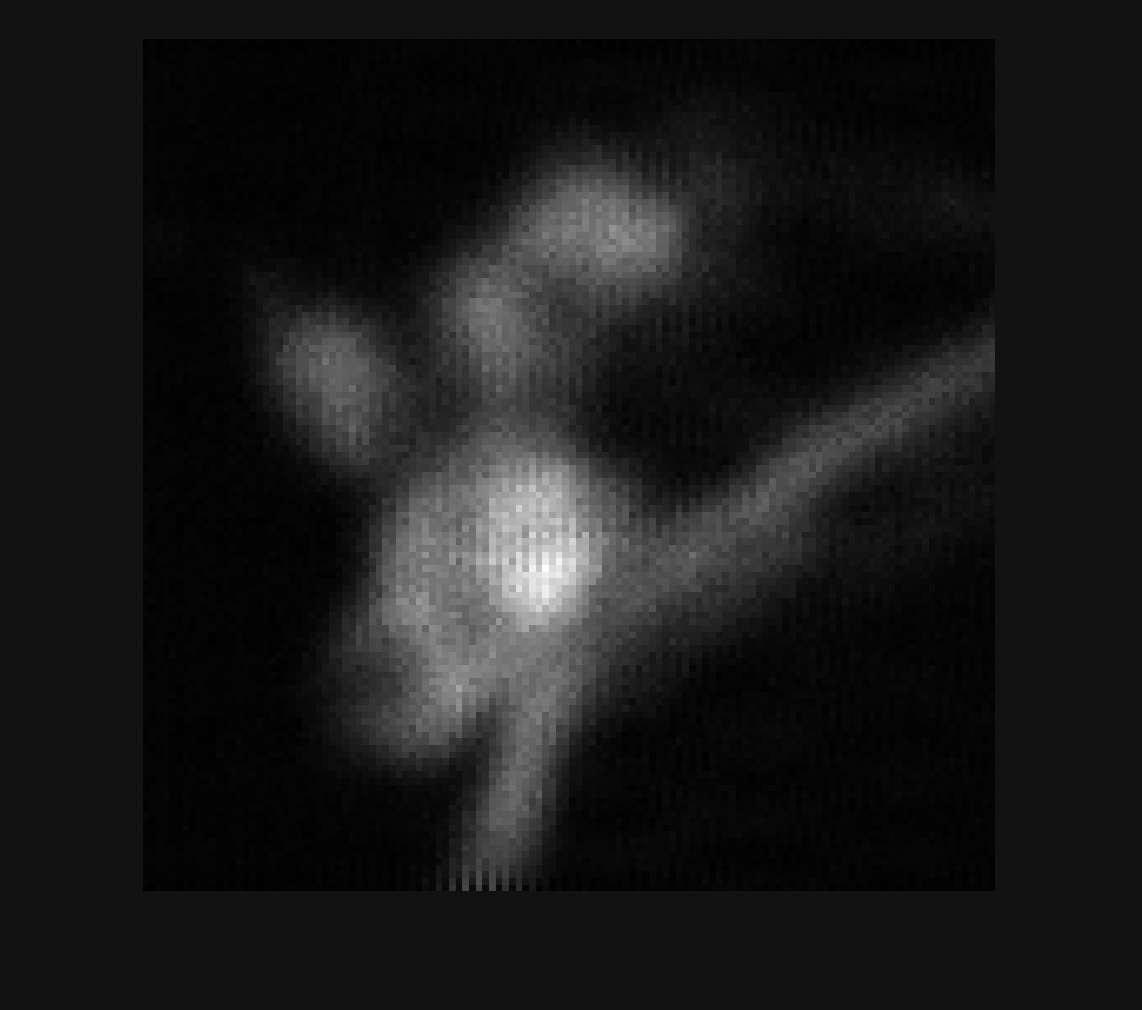

neuron_slice = 7; % try experimenting with different values

% extract SOIs
SOIs = extractSOIs(volumes, neuron_slice, num_total_slices);

% Compute mean (along the third /stack dimension)
mean_SOI = mean(SOIs, 3);

% Display meanSOI
imshow(mean_SOI,[], "InitialMagnification", 500); 

Now we can see the regions of activity much better. For slice 7 in the volume, there are 4 activity regions. Let's capture them using 4 ROIs.

### Defining ROIs

There are multiple ways of defining ROIs. For this example, we will use the drawpolygon function, which is the easiest for our purposes.

We will draw four ROIs on the image using the following code:

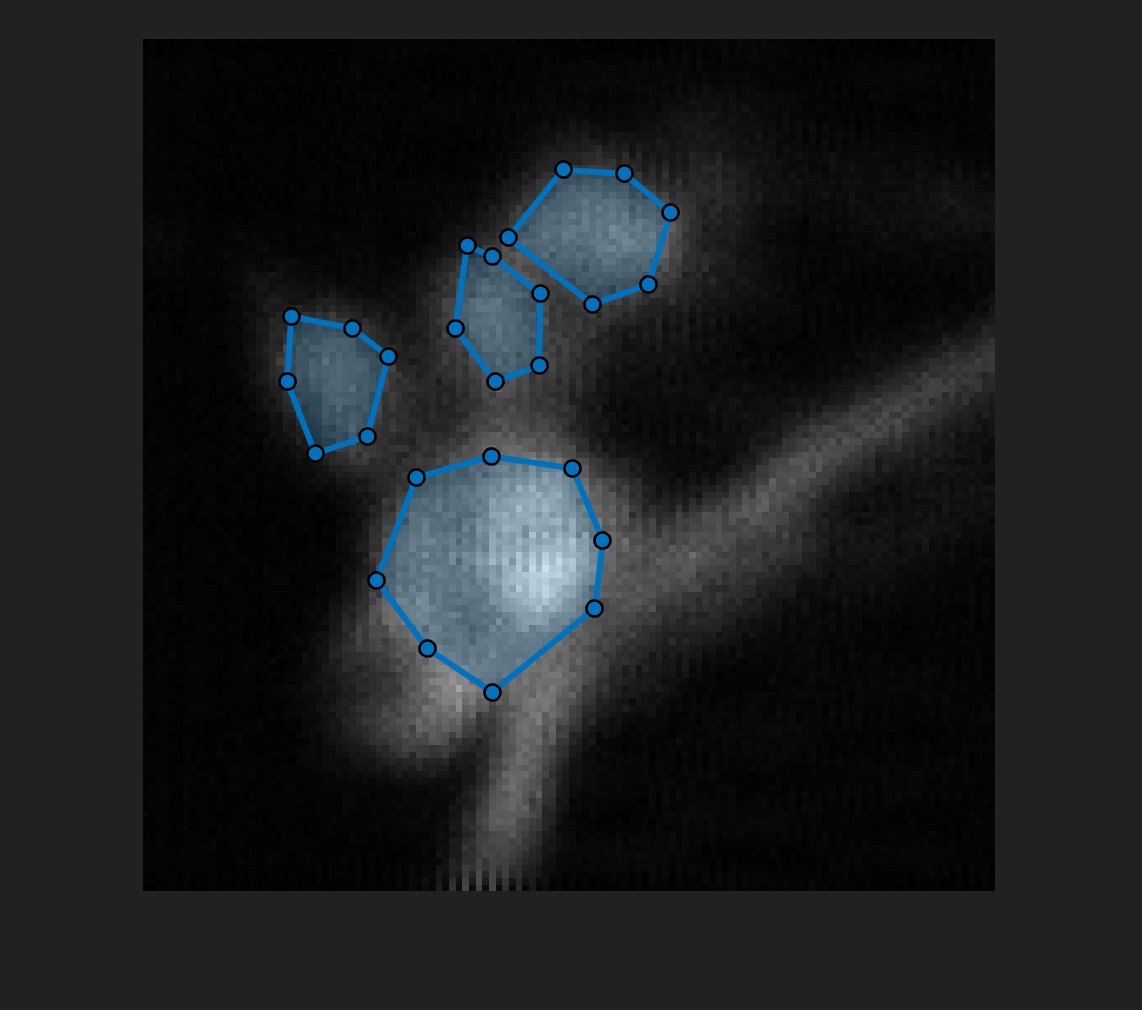

num_roi = 4;
h = figure('Position', [0, 0, 800, 600]);
imshow(mean_SOI,[], "InitialMagnification", 500, 'Parent', gca);
roi = cell(num_roi, 1); % Cell structure to save all our ROIs
for i=1:num_roi
    poly = drawpolygon;
    roi{i} = poly.Position;
end

### Computing fluorescence 

Once the ROI is defined, the have to define what the mean by fluorescence activity in the ROI. Typically, this is defined as the average signal in the ROI but one can define it in other ways, like sum of all activity in the ROI. Here, we will define fluorescence as average activity.

For each slice, we will select all the pixels in the ROI, compute the average. So for each ROI, we will have one value of every volume.

fluorescence = zeros(num_volumes, num_roi);

for i=1:num_roi

    % Pick an ROI
    curr_roi = round(roi{i});

    % Go through each volume and compute the average fluoroscence
    for j=1:num_volumes

        curr_slice = SOIs(:,:,j);
        fluorescence(j, i) = mean(curr_slice(curr_roi), "all");
    
    end

end

Now, let's plot them and see it looks.

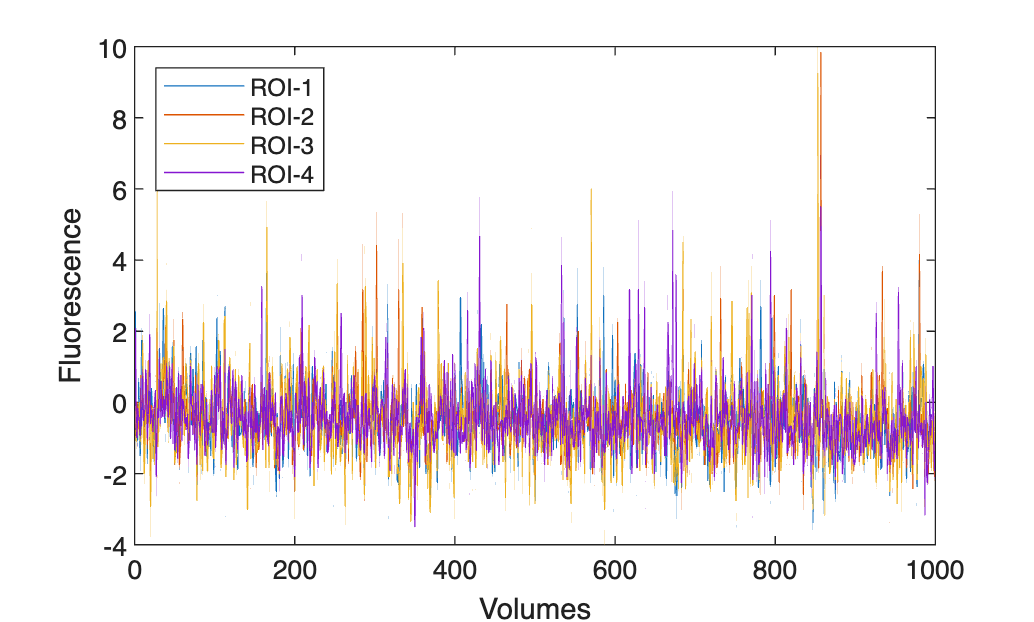

plot(fluorescence)
legend({"ROI-1", "ROI-2", "ROI-3", "ROI-4"}, 'Location', 'northwest')
xlabel("Volumes")
ylabel("Fluorescence")

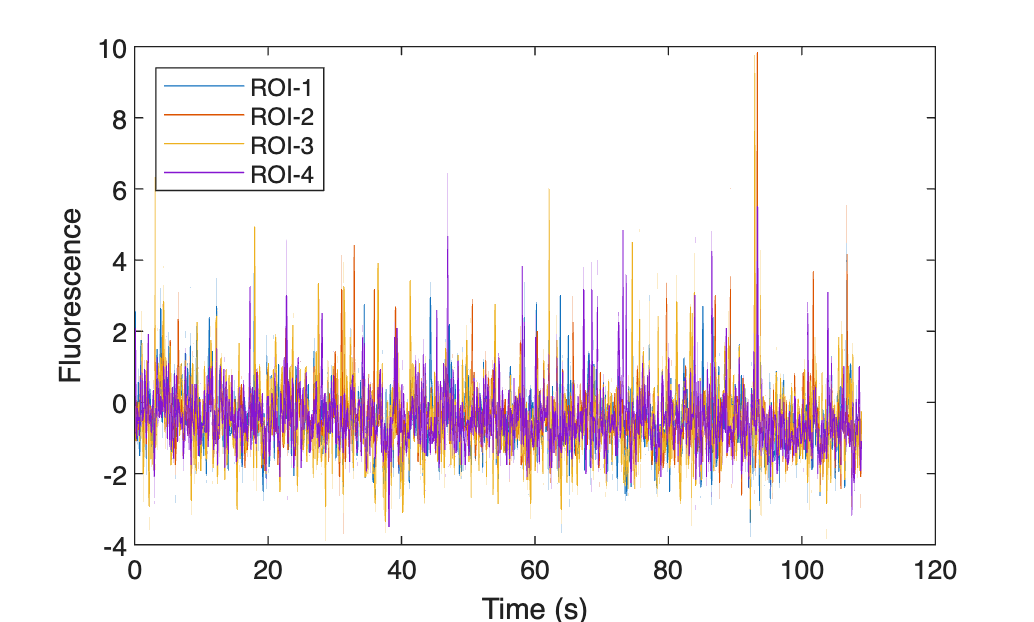

% Find volume rate and get changes in fluorescence with time
vol_rate = f_meta.hRoiManager.scanVolumeRate;
time = (1:num_volumes)/vol_rate;

% Plot fluorescence with time
plot(time, fluorescence)
legend({"ROI-1", "ROI-2", "ROI-3", "ROI-4"}, 'Location', 'northwest')
xlabel("Time (s)")
ylabel("Fluorescence (a.u.)")

### Computing neural activity

Fluorescence is a good measure of calcium in the neurons of interest. However, calcium is not a good proxy for neuronal activity as calcium increases quickly with action potentials, but takes longer to decay. So pulling out neural activity from calcium fluorescence is tricky. Additionally, fluorescence will slowly decay over time because GCaMP slowly photobleaches, so we need to account for it as well.

The common way of accounting for photobleaching and partially the slow decay of GCaMP is by computing $\frac{\Delta F}{F_0 }$, which is essentially change in fluorescence with respect to a baseline (that can shift over time). 

Let's take one ROI as an example and compute  $\frac{\Delta F}{F_0 }$. The baseline ($F_0$) is hard to estimate, but one way to estimate it is to compute the average fluorescence over a short window (this should capture changes in fluorescence due to bleaching and the calcium build up related fluorescence).

% Pick an ROI
curr_f = fluorescence(:, 2);

% average over a window of 5 seconds
window_time = 10; %sec
window_size = round(window_time * vol_rate)

window_size = 92

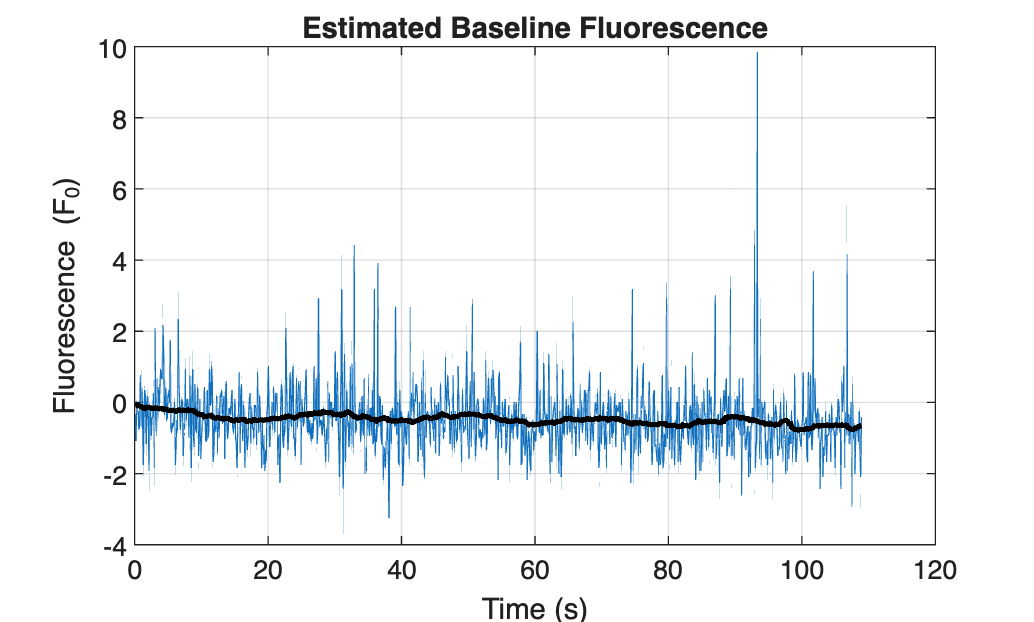

% Compute the baseline fluorescence F_0 using a moving average
baseline_f = movmean(curr_f, window_size);

% Plot the baseline fluorescence
plot(time, curr_f);
hold on, plot(time, baseline_f, 'LineWidth', 2, 'color', 'k');
xlabel("Time (s)");
ylabel("Fluorescence (F_0)");
title("Estimated Baseline Fluorescence");
grid on;

Compute the $\frac{\Delta F}{F_0 }$ = $\frac{F-F_0 }{\left\|F_0 \right\|}$.

Note the similarity to a standard normal distribution. If one assumes that the mean and the standard deviation are the same (which is typical for noise associated with PMT), then by computing $\frac{\Delta F}{F_0 }$, we can easily put thresholds on the activity.

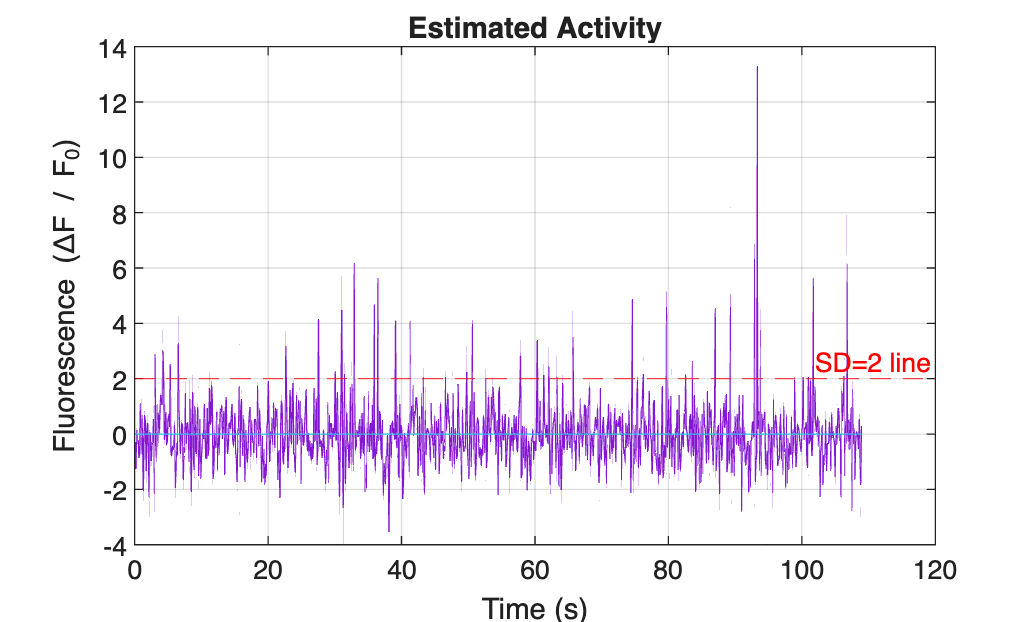

df_f = (curr_f - baseline_f)/abs(baseline_f);

% Plot the df_f fluorescence
figure;
plot(time, df_f);
yline(2, 'r--', "SD=2 line")

xlabel("Time (s)");
ylabel("Fluorescence (\DeltaF / F_0)");
title("Estimated Activity");
grid on;